model = createpde("thermal","transient");

Import the disc geometry.

importGeometry(model,"cau_truc\break_disk\Brake_Piston_1.stl");

Plot the geometry with the face labels.    

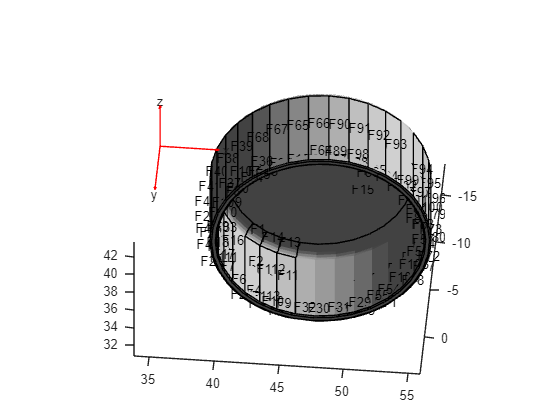

figure
pdegplot(model,"FaceLabels","on");
view([-5 -47])

Generate a fine mesh with a small target maximum element edge length. The resulting mesh has more than 130000 nodes (degrees of freedom).

generateMesh(model,"Hmax",0.005);

Mesh failed. Operation terminated by user.

Plot the Mesh

figure
pdemesh(model)
view([0,90])

Specify the thermal properties of the material.

thermalProperties(model,"ThermalConductivity",100, ...
                        "MassDensity",8000, ...
                        "SpecificHeat",500);

Specify the boundary conditions. All the faces are exposed to air, so there will be free convection.

thermalBC(model,"Face",1:model.Geometry.NumFaces, ...
                "ConvectionCoefficient",10, ...
                "AmbientTemperature",30);

Model the moving heat source by using a function handle that defines the thermal load as a function of space and time. For the definition of the `movingHeatSource` function, see the Heat Source Functions section at the bottom of this page.

thermalBC(model,"Face",11,"HeatFlux",@movingHeatSource); 
thermalBC(model,"Face",4,"HeatFlux",@movingHeatSource); 

Specify the initial temperature.

thermalIC(model,30);

Solve the model for the time steps from 0 to 25 ms.

tlist = linspace(0,0.025,100); % Half revolution
R1 = solve(model,tlist);

Plot the temperature distribution at 25 ms.

figure("units","normalized","outerposition",[0 0 1 1])
pdeplot3D(model,"ColorMapData",R1.Temperature(:,end))